# Experiment 7

We compare the three-phase power flow solutions obtained using the proposed Quadratic Approximation in Transformer Polar Coordinates (QTPC) with those of the exact AC formulation over numerous MATPOWER test cases **under unbalanced conditions**. We consire the following scenarios for unbalanced operation:

- Unbalanced load: 

- Unbalanced line parameters:

- Unbalanced load & unbalanced line parameters:

For each scenario, the following performance metrics are calculated:

- The *Root Mean Square Error* *(RMSE)*, both for voltage angles and voltage magnitudes for each phase defined as:

$RMSE(\mathbf{V}_{a,\phi}) = \frac{\left|\left|\mathbf{V}_{a,\phi}^{QTPC}-\mathbf{V}_{a,\phi}^{AC}\right|\right|_2}{\sqrt{n_{\mathcal{B}}}}$,  $RMSE(\mathbf{V}_{m,\phi}) = \frac{\left|\left|\mathbf{V}_{m,\phi}^{QTPC}-\mathbf{V}_{m,\phi}^{AC}\right|\right|_2}{\sqrt{n_{\mathcal{B}}}}}$, $\forall \phi \in \{ a,b,c\}$

            where $n_{\mathcal{B}}}$ is the number of system buses.

- The *Maximum Percentage Relative Error (MPRE) *for voltage magnitudes defined as:

$$MPRE(\mathbf{V}_{m,\phi})=\max\left\{\frac{\left| \mathbf{V}_{m,\phi}^{QTPC} - \mathbf{V}_{m,\phi}^{AC}  \right|}{\left|\mathbf{V}_{m,\phi}^{AC} \right|} \times 100\% \right\}$ $, $\forall \phi \in \{ a,b,c\}$

- The *number of Newton-Raphson iterations* required to reach a solution within the default MATPOWER tolerance.

- The elapsed time for finding the solutions for both formulations.

We begin by defining the MATPOWER test cases that will be used in this experiment, ordered by an increasing number of buses:

transmission = {'case4gs', 'case5', 'case6ww', 'case9', 'case30', 'case_ieee30', 'case39', 'case118',...
         'case_ACTIVSg200', 'case_ACTIVSg500'};

distribution = {'case4_dist', 'case10ba', 'case12da', 'case15da', ...
             'case18', 'case22', 'case28da', 'case33bw', 'case38si', ...
             'case51ga',  'case69', 'case85', ...
             'case94pi', 'case118zh', 'case141'};

ids = [1 2 3 4 7 8 9 14 16 18 25 26 27 28 32 34 35 36 39 40 42 45 46 47 48]';

cases = [transmission distribution];

Now, we define the MATPOWER options for running power flows under the AC, QTPC, and LTPC formulations:

mpopt_ac = mpoption('out.all',0,'verbose',0);
mpopt_qtpc = mpoption('model','TPC','out.all',0,'verbose',0);
mpopt_ltpc = mpoption('model','TPC','out.all',0,'verbose',0);
mpopt_qtpc.pf.tpc.form = 'QUAD';
mpopt_ltpc.pf.tpc.form = 'LIN';

Then, we define the unbalancing strategy to be applied and the desired number of samples with successful convergence:

unbal_strategy = {'line_params','load'};   % Provide a cell array of strings with the options: 'load' or 'line_params'
ns = 100;

Afterward, we loop through all the test cases and run power flows using the three formulations, setting a flat start for each of them:

rng(2);
define_constants;
nc = length(cases);
num_ite = zeros(nc,ns,2);
et = zeros(nc,ns,3);
overall_counter = zeros(nc,1);
for c = 1:nc
    mpc3p_base = mp.case_utils.convert_1p_to_3p(cases{c});
    nb = size(mpc3p_base.bus3p,1);
    counter = 0;
    e = 1;
    while e <= ns
        mpc3p = unbalance_case(mpc3p_base,unbal_strategy);
        mpc3p.bus3p(:,[4 5 6]) = ones(nb,3);
        mpc3p.bus3p(:,[7 8 9]) = repmat([0 -120 120], nb, 1);
        res_ac = run_pf(mpc3p,mpopt_ac,'mpx',mp.xt_3p);
        mpc3p.bus3p(:,[7 8 9]) = zeros(nb,3);
        res_qtpc = run_pf(mpc3p,mpopt_qtpc,'mpx',wgv.xt_tpc_3p);  % we use the three-phase tpc extension with quadratic model
        res_ltpc = run_pf(mpc3p,mpopt_ltpc,'mpx',wgv.xt_tpc_3p);  % we use the three-phase tpc extension with linear model
        success = [res_ac.mm.soln.eflag
                   res_qtpc.mm.soln.eflag
                   res_ltpc.mm.soln.eflag]';

        if sum(success) == 3
            va_ac(e).(cases{c}) = table2array(res_ac.dm.elements.bus3p.tab(:,["va1","va2","va3"]));
            vm_ac(e).(cases{c}) = table2array(res_ac.dm.elements.bus3p.tab(:,["vm1","vm2","vm3"]));
            va_qtpc(e).(cases{c}) = table2array(res_qtpc.dm.elements.bus3p.tab(:,["va1","va2","va3"]));
            vm_qtpc(e).(cases{c}) = table2array(res_qtpc.dm.elements.bus3p.tab(:,["vm1","vm2","vm3"]));
            va_ltpc(e).(cases{c}) = table2array(res_ltpc.dm.elements.bus3p.tab(:,["va1","va2","va3"]));
            vm_ltpc(e).(cases{c}) = table2array(res_ltpc.dm.elements.bus3p.tab(:,["vm1","vm2","vm3"]));

            num_ite(c,e,:) = [res_ac.mm.soln.output.iterations
                res_qtpc.mm.soln.output.iterations]';
            et(c,e,:) = [res_ac.mm.soln.output.et
                res_qtpc.mm.soln.output.et
                res_ltpc.mm.soln.output.et]';
            e = e + 1;
        end
        counter = counter + 1;
    end
    overall_counter(c) = counter;
end

Now, we compute all the remaining performance metrics and display them in a single table:

rmse_va_qtpc = zeros(ns,3,nc);
rmse_vm_qtpc = zeros(ns,3,nc);
mpre_vm_qtpc = zeros(ns,3,nc);

rmse_va_ltpc = zeros(ns,3,nc);
rmse_vm_ltpc = zeros(ns,3,nc);
mpre_vm_ltpc = zeros(ns,3,nc);

for c = 1:nc
    C = cases{c};
    nb = size(vm_ac(1).(C),1);
    for e = 1:ns        
        rmse_va_qtpc(e,:,c) = 1/sqrt(nb) * vecnorm(va_qtpc(e).(C) - va_ac(e).(C));
        rmse_vm_qtpc(e,:,c) = 1/sqrt(nb) * vecnorm(vm_qtpc(e).(C) - vm_ac(e).(C));
        mpre_vm_qtpc(e,:,c) = max(abs( (vm_qtpc(e).(C) - vm_ac(e).(C)) ./ vm_ac(e).(C))) * 100;

        rmse_va_ltpc(e,:,c) = 1/sqrt(nb) * vecnorm(va_ltpc(e).(C) - va_ac(e).(C));
        rmse_vm_ltpc(e,:,c) = 1/sqrt(nb) * vecnorm(vm_ltpc(e).(C) - vm_ac(e).(C));
        mpre_vm_ltpc(e,:,c) = max(abs( (vm_ltpc(e).(C) - vm_ac(e).(C)) ./ vm_ac(e).(C))) * 100;
    end
end

Finally, we show the boxplots of the error metrics, for the QTPC first, and ... 

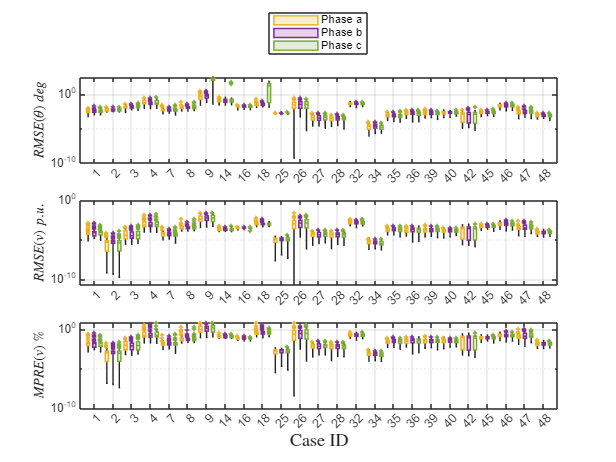

rmse_va = reshape(rmse_va_qtpc,ns,nc*3,[]);
rmse_vm = reshape(rmse_vm_qtpc,ns,nc*3,[]);
mpre_vm = reshape(mpre_vm_qtpc,ns,nc*3,[]);

string_of_Ids = mat2cell(num2str(ids),ones(nc,1))';
all_Ids = repmat(string_of_Ids,3*ns,1); all_Ids = all_Ids(:);
categ_Ids = categorical(all_Ids,string_of_Ids);
labels = repmat({'Phase a','Phase b','Phase c'},ns,nc); labels = labels(:);

figure;
tl = tiledlayout(3,1);
nexttile
b1 = boxchart(categ_Ids,rmse_va(:),'GroupByColor',labels,'MarkerStyle','+','MarkerSize',3);
box on
grid on
set(gca,'YScale','log');
set(gca,'GridAlpha',0.1,'MinorGridAlpha',0.07)
ylabel('$RMSE(\theta) \; deg$','Interpreter','latex')
b1(1).SeriesIndex = 3;
b1(2).SeriesIndex = 4;
b1(3).SeriesIndex = 5;

nexttile
b2 = boxchart(categ_Ids,rmse_vm(:),'GroupByColor',labels,'MarkerStyle','+','MarkerSize',3);
box on
grid on
set(gca,'YScale','log');
set(gca,'GridAlpha',0.1,'MinorGridAlpha',0.07)
ylabel('$RMSE(v) \; p.u.$','Interpreter','latex')
b2(1).SeriesIndex = 3;
b2(2).SeriesIndex = 4;
b2(3).SeriesIndex = 5;

nexttile
b3 = boxchart(categ_Ids,mpre_vm(:),'GroupByColor',labels,'MarkerStyle','+','MarkerSize',3);
box on
grid on
set(gca,'YScale','log');
set(gca,'GridAlpha',0.1,'MinorGridAlpha',0.07)
ylabel('$MPRE(v) \; \%$','Interpreter','latex')
b3(1).SeriesIndex = 3;
b3(2).SeriesIndex = 4;
b3(3).SeriesIndex = 5;

xlabel(tl,'Case ID','Interpreter','latex')
lgnd = legend;
lgnd.Layout.Tile = 'north';

... for the QTPC vs LTPC, per-phase, secondly:

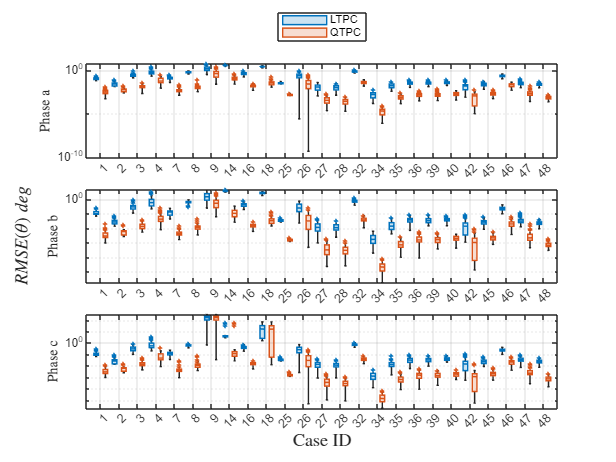

labels = repmat({'QTPC','LTPC'},ns*nc,1); labels = labels(:);
phases = {'a','b','c'};

figure;
tl = tiledlayout(3,1);
for p = 1:3
    rmse_vm_qtpc_p = rmse_va_qtpc(:,p,:);
    rmse_vm_qtpc_p = reshape(rmse_vm_qtpc_p,ns,nc,[]);
    rmse_vm_ltpc_p = rmse_va_ltpc(:,p,:);
    rmse_vm_ltpc_p = reshape(rmse_vm_ltpc_p,ns,nc,[]);
    rmse_va = [rmse_vm_qtpc_p rmse_vm_ltpc_p];

    string_of_Ids = mat2cell(num2str(ids),ones(nc,1))';
    all_Ids = repmat(string_of_Ids,ns,1); all_Ids = all_Ids(:);
    categ_Ids = categorical(all_Ids,string_of_Ids); categ_Ids = repmat(categ_Ids,1,2);   

    nexttile
    boxchart(categ_Ids(:),rmse_va(:),'GroupByColor',labels,'MarkerStyle','+','MarkerSize',3)
    box on
    grid on
    set(gca,'YScale','log');
    set(gca,'GridAlpha',0.1,'MinorGridAlpha',0.07)
    ylabel(sprintf('Phase %s',phases{p}),'Interpreter','latex')
end
xlabel(tl,'Case ID','Interpreter','latex')
ylabel(tl,'$RMSE(\theta) \; deg$','Interpreter','latex')
lgnd = legend;
lgnd.Layout.Tile = 'north';

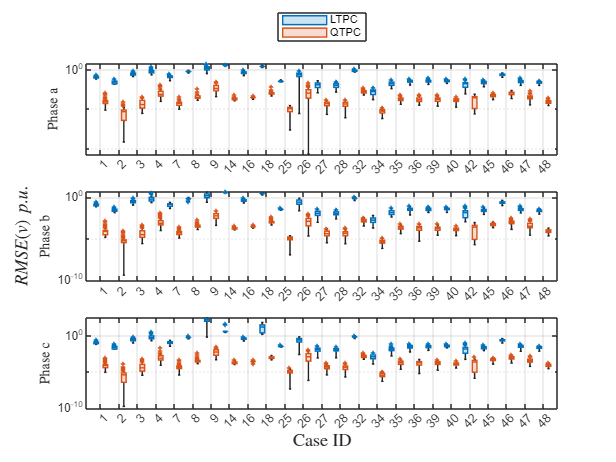


figure;
tl = tiledlayout(3,1);
for p = 1:3
    rmse_vm_qtpc_p = rmse_vm_qtpc(:,p,:);
    rmse_vm_qtpc_p = reshape(rmse_vm_qtpc_p,ns,nc,[]);
    rmse_vm_ltpc_p = rmse_va_ltpc(:,p,:);
    rmse_vm_ltpc_p = reshape(rmse_vm_ltpc_p,ns,nc,[]);
    rmse_vm = [rmse_vm_qtpc_p rmse_vm_ltpc_p];

    string_of_Ids = mat2cell(num2str(ids),ones(nc,1))';
    all_Ids = repmat(string_of_Ids,ns,1); all_Ids = all_Ids(:);
    categ_Ids = categorical(all_Ids,string_of_Ids); categ_Ids = repmat(categ_Ids,1,2);   

    nexttile
    boxchart(categ_Ids(:),rmse_vm(:),'GroupByColor',labels,'MarkerStyle','+','MarkerSize',3)
    box on
    grid on
    set(gca,'YScale','log');
    set(gca,'GridAlpha',0.1,'MinorGridAlpha',0.07)
    ylabel(sprintf('Phase %s',phases{p}),'Interpreter','latex')
end
xlabel(tl,'Case ID','Interpreter','latex')
ylabel(tl,'$RMSE(v) \; p.u.$','Interpreter','latex')
lgnd = legend;
lgnd.Layout.Tile = 'north';

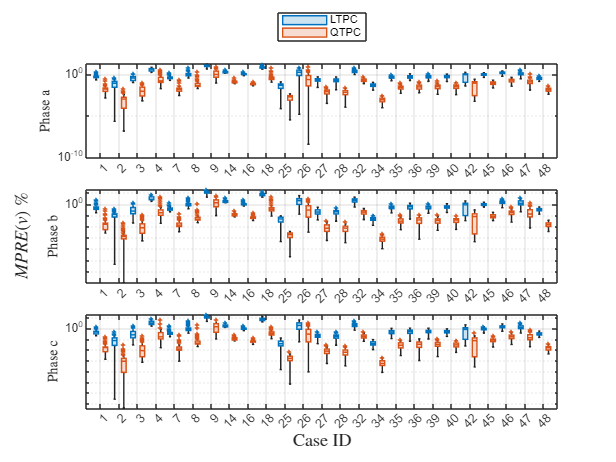

figure;
tl = tiledlayout(3,1);
for p = 1:3
    mpre_vm_qtpc_p = mpre_vm_qtpc(:,p,:);
    mpre_vm_qtpc_p = reshape(mpre_vm_qtpc_p,ns,nc,[]);
    mpre_vm_ltpc_p = mpre_vm_ltpc(:,p,:);
    mpre_vm_ltpc_p = reshape(mpre_vm_ltpc_p,ns,nc,[]);
    mpre_vm = [mpre_vm_qtpc_p mpre_vm_ltpc_p];

    string_of_Ids = mat2cell(num2str(ids),ones(nc,1))';
    all_Ids = repmat(string_of_Ids,ns,1); all_Ids = all_Ids(:);
    categ_Ids = categorical(all_Ids,string_of_Ids); categ_Ids = repmat(categ_Ids,1,2);   

    nexttile
    boxchart(categ_Ids(:),mpre_vm(:),'GroupByColor',labels,'MarkerStyle','+','MarkerSize',3)
    box on
    grid on
    set(gca,'YScale','log');
    set(gca,'GridAlpha',0.1,'MinorGridAlpha',0.07)
    ylabel(sprintf('Phase %s',phases{p}),'Interpreter','latex')
end
xlabel(tl,'Case ID','Interpreter','latex')
ylabel(tl,'$MPRE(v) \; \%$','Interpreter','latex')
lgnd = legend;
lgnd.Layout.Tile = 'north';

function mpc_out = unbalance_case(mpc_in,unbalancing)
    mpc_out = mpc_in;
    if any(ismember(upper(unbalancing),{'LOAD'}))
        nl = size(mpc_in.load3p,1);
        id_phase_ldpf = randi(3,1,nl);
        id_phase_kW = randi(3,1,nl);
        old_ldpf = mpc_out.load3p(:,7:9);
        old_kW = mpc_out.load3p(:,4:6);
        val_max_ldpf = 1;
        val_min_ldpf = 0.5;
        new_ldpf = ((val_max_ldpf - val_min_ldpf)*rand(nl,1) + val_min_ldpf).*sign(randn(nl,1));
        val_max_kW = 1.25; % percentage
        val_min_kW = 0.75; % percentage
        new_kW = (val_max_kW - val_min_kW)*rand(nl,1) + val_min_kW;

        old_ldpf(sub2ind(size(old_ldpf), 1:nl, id_phase_ldpf)) = new_ldpf;
        old_kW(sub2ind(size(old_kW), 1:nl, id_phase_kW)) = new_kW;
        mpc_out.load3p(:,4:6) = old_kW;
        mpc_out.load3p(:,7:9) = old_ldpf;
    end
    if any(ismember(upper(unbalancing),{'LINE_PARAMS'}))
        nl = size(mpc_in.line3p,1);
        % Diagonal values
        min_factor_diagR = 0.98;
        max_factor_diagR = 1.1;
        min_factor_diagX = 1.18;
        max_factor_diagX = 1.3;
        min_factor_diagC = 0.14;
        max_factor_diagC = 0.19;
        vals_diagR = (max_factor_diagR - min_factor_diagR)*rand(nl,3) + min_factor_diagR;
        vals_diagX = (max_factor_diagX - min_factor_diagX)*rand(nl,3) + min_factor_diagX;
        vals_diagC = (max_factor_diagC - min_factor_diagC)*rand(nl,3) + min_factor_diagC;

        % Off-diagonal values
        %  Resistance
        min_factor_Rab = 0.89;
        max_factor_Rab = 1.2;
        min_factor_Rac = 0.86;
        max_factor_Rac = 1.13;
        min_factor_Rbc = 0.92;
        max_factor_Rbc = 1.27;
        vals_Rab = (max_factor_Rab - min_factor_Rab)*rand(nl,1)+min_factor_Rab;
        vals_Rac = (max_factor_Rac - min_factor_Rac)*rand(nl,1)+min_factor_Rac;
        vals_Rbc = (max_factor_Rbc - min_factor_Rbc)*rand(nl,1)+min_factor_Rbc;

        %  Reactance
        min_factor_Xab = 0.85;
        max_factor_Xab = 1.1;
        min_factor_Xac = 0.8;
        max_factor_Xac = 1.0;
        min_factor_Xbc = 0.9;
        max_factor_Xbc= 1.25;
        vals_Xab = (max_factor_Xab - min_factor_Xab)*rand(nl,1)+min_factor_Xab;
        vals_Xac = (max_factor_Xac - min_factor_Xac)*rand(nl,1)+min_factor_Xac;
        vals_Xbc = (max_factor_Xbc - min_factor_Xbc)*rand(nl,1)+min_factor_Xbc;

        %  Capacitance
        min_factor_Cab = 0.10;
        max_factor_Cab = 0.20;
        min_factor_Cac = 0.05;
        max_factor_Cac = 0.13;
        min_factor_Cbc = 0.11;
        max_factor_Cbc = 0.4;
        vals_Cab = (max_factor_Cab - min_factor_Cab)*rand(nl,1)+min_factor_Cab;
        vals_Cac = (max_factor_Cac - min_factor_Cac)*rand(nl,1)+min_factor_Cac;
        vals_Cbc = (max_factor_Cbc - min_factor_Cbc)*rand(nl,1)+min_factor_Cbc;

        % Final values
        valsR = [vals_diagR(:,1) vals_Rab vals_Rac vals_diagR(:,2) vals_Rbc vals_diagR(:,3)];
        valsX = [vals_diagX(:,1) vals_Xab vals_Xac vals_diagX(:,2) vals_Xbc vals_diagX(:,3)];
        valsC = [vals_diagC(:,1) vals_Cab vals_Cac vals_diagC(:,2) vals_Cbc vals_diagC(:,3)];

        mpc_out.lc(:,2:end) = mpc_out.lc(:,2:end) .* [valsR valsX valsC];
    end
end